close all
clear all


%%Inspired by Christopher Roemmelmayer
%%Implemented by Felix Kaiser



# Pandemie Simulator

Mit diesem Tool können anhand realen Daten verschiedene Ausbreitungsszenarien einer Pandemie in einer Population simuliert werden. 

## Annahmen

- Ein Krankheitsverlauf ist eine Sequenz von Inkubationszeit, Symptome zeigender Zeit (ansteckend), im Falle eines schweren Verlaufs einer Lungenentzündung, im Falle eines sehr schweren Verlaufs einer Zeit auf der Intensivstation und evtl dem Tod.

                                                                                                     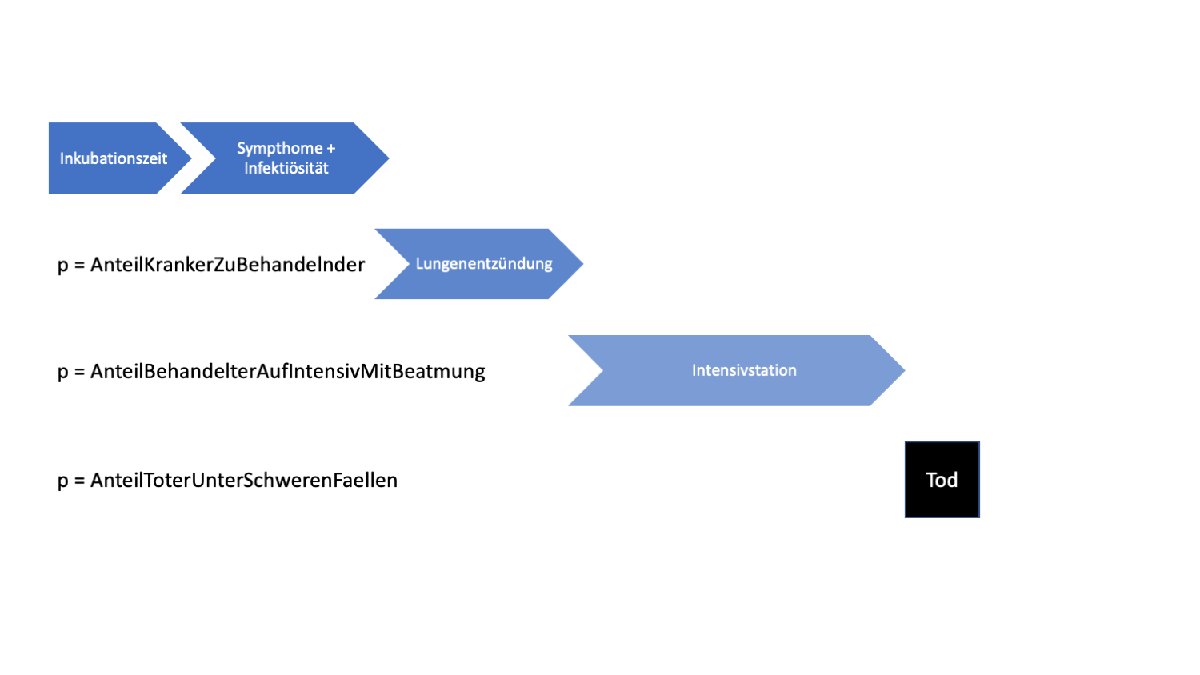

Quelle heirfür ist der [Corona-Steckbrief des RKI](https://www.rki.de/DE/Content/InfAZ/N/Neuartiges_Coronavirus/Steckbrief.html)

- Die Basisreproduktionszahl gibt an, wie viele Menschen eine infizeirte Person in ihrer infektiösen Phase im Durchschnitt ansteckt, falls die betroffene Bevölkerung weder geimpft oder immun ist. Diese kann in dieser Simulation verändert werden, um die unterschiedlichen Ausbreitungsgeschwindigkeiten der Krankheit bei keinen Maßnahmen oder Social Distancing abzubilden.

- Die Nettoreproduktionszahl gibt an, wie viele Menschen eine Person in der infektiösen Phase im Durchschnitt infiziert.

                
$$\textrm{Nettoreproduktionszahl}=\textrm{Basisreproduktionszahl}*\left(1-p_{\textrm{Immune}\;\textrm{Population}} \right)$$


- DIe Anzahl der Neuinfizierten am Tag $t_{\textrm{heute}}$ errechnet sich aus:

                
$$\textrm{Neuinfektionen}\left(t_{\textrm{heute}} \right)=\sum_{t=t_{\textrm{heute}} -\left(\textrm{Inkubationszeit}+\textrm{Infektiösezeit}\right)}^{t_{\textrm{heute}} -\textrm{Inkubationszeit}} \textrm{Neuinfektionen}\left(t\right)*\frac{\textrm{Nettoreproduktionszahl}\left(t\right)}{\textrm{InfektiöseZeit}}$$


- Bereits Infizierte können nicht nochmals angesteckt werden und sind somit immun.

## Parameter 


AnteilImmuner = 0;

Basisreproduktionszahl = 2.5; % Source: RKI gibt an, wie viele Menschen eine bereits erkrankte Person im Durchschnitt infiziert, falls die betroffene Bevölkerung weder geimpft noch anderweitig vor der Übertragung geschützt wird
Nettoreproduktionszahl = Basisreproduktionszahl * (1-AnteilImmuner); % Source WIKI
Vorhersagezeitraum = 500;

AnteilKrankerZuBehandelnder =0.15;% Konservative Wahrscheinlichkeiten, behandelt werden zu müssen
AnteilBehandelterAufIntensivMitBeatmung =0.5;%Intensiv behandelt werden zu müssen
AnteilToterUnterSchwerenFaellen_WennBeatmet =0.22; % zu sterben
AnteilToterUnterSchwerenFaellen_WennNichtBeatmet = 0.8;

Population = ones(1,Vorhersagezeitraum)* 80000000;

Inkubationszeit =5; %Source RKI Steckbrief
InfektioeseZeit =4;
PneunmonieZeit =3;
KrankenhausPhase =14;


PARAMETERAUSGABE = 1;
if(PARAMETERAUSGABE) 
    Basisreproduktionszahl% Source: RKI gibt an, wie viele Menschen eine bereits erkrankte Person im Durchschnitt infiziert, falls die betroffene Bevölkerung weder geimpft noch anderweitig vor der Übertragung geschützt wird
    Vorhersagezeitraum
    AnteilKrankerZuBehandelnder% Konservative Wahrscheinlichkeiten, behandelt werden zu müssen
    AnteilBehandelterAufIntensivMitBeatmung%Intensiv behandelt werden zu müssen
    AnteilToterUnterSchwerenFaellen_WennBeatmet% zu sterben
    AnteilToterUnterSchwerenFaellen_WennNichtBeatmet
    Population(1)
    Inkubationszeit%Source RKI Steckbrief
    InfektioeseZeit
    PneunmonieZeit
    KrankenhausPhase
end

Basisreproduktionszahl = 2.5000

Vorhersagezeitraum = 500

AnteilKrankerZuBehandelnder = 0.1500

AnteilBehandelterAufIntensivMitBeatmung = 0.5000

AnteilToterUnterSchwerenFaellen_WennBeatmet = 0.2200

AnteilToterUnterSchwerenFaellen_WennNichtBeatmet = 0.8000

ans = 80000000

Inkubationszeit = 5

InfektioeseZeit = 4

PneunmonieZeit = 3

KrankenhausPhase = 14


neuInfizierteAmTag = zeros(1,Vorhersagezeitraum+8);
bisherInfizierteAmTag = zeros(1,Vorhersagezeitraum);
geneseneAmTag = zeros(1,Vorhersagezeitraum);
InkubierendeInfizierteAmTag = zeros(1, Vorhersagezeitraum);
InfektioeseInfizierteAmTag = zeros(1,Vorhersagezeitraum);
ZubehandelndeInfizierteAmTag = zeros(1,Vorhersagezeitraum);
IntensivPatientenAmTag = zeros(1,Vorhersagezeitraum);
anteilBeatmeterIntensivPatienten = zeros(1,Vorhersagezeitraum);
ToteAmTag= zeros(1,Vorhersagezeitraum);
bisherToteAmTag= zeros(1,Vorhersagezeitraum);
neuGeneseneAmTag = zeros(1,Vorhersagezeitraum);
AnteilImmuner = zeros(1,Vorhersagezeitraum);
BasisreproduktionsrateArray = ones(1,Vorhersagezeitraum);
NettoreproduktionszahlArray = ones(1,Vorhersagezeitraum);



## Startbedingungen

Als Startbedingungen sind die[ Zahlen des Robert-Koch-Instituts](https://www.rki.de/DE/Content/InfAZ/N/Neuartiges_Coronavirus/Fallzahlen.html)  oder der John Hopkins Universität wählbar. 

STARTDATEN = "John-Hopkins"

STARTDATEN = "John-Hopkins"

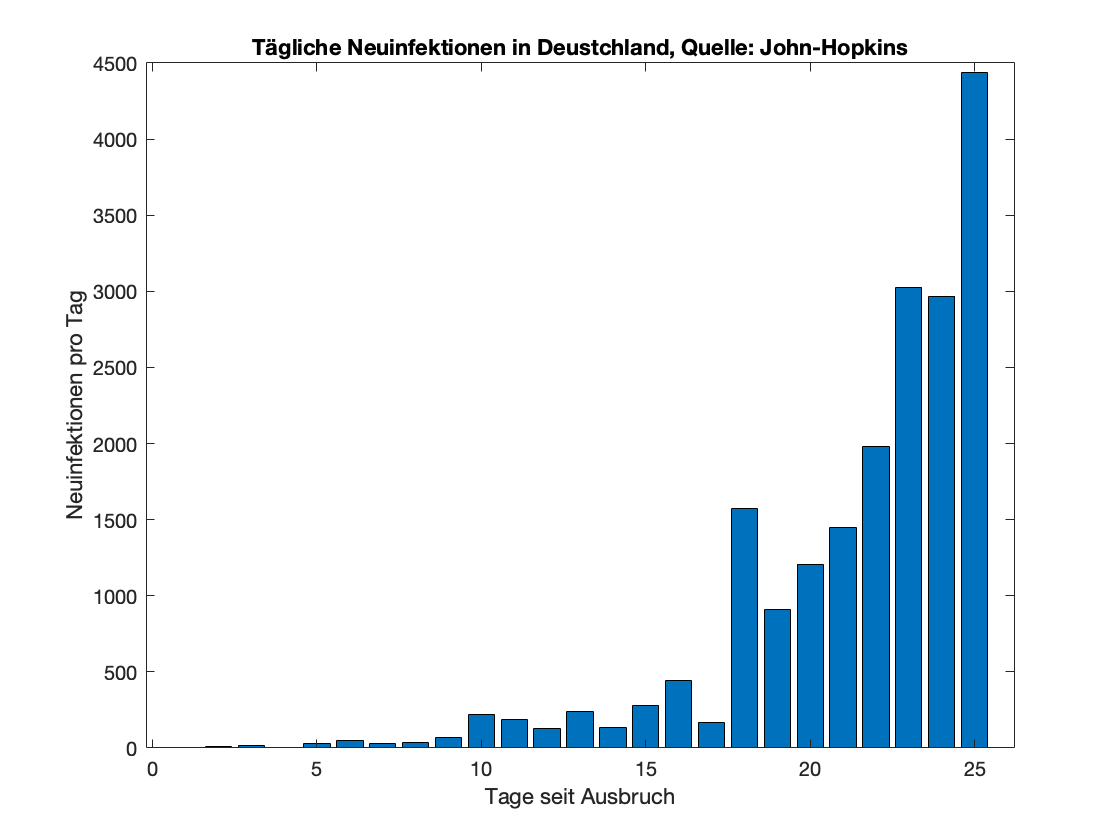


if(STARTDATEN == 'Robert-Koch')

    anstiegFaelleInGerProTagHistory = [2;3;5;27;13; 51;33;38;52;160;239;156;107;237;157;271;802;693;733;1043;1174;1144;1042;2801;2958];

else
    
    data = readtable('JohnHopkins_21.03_Deutschland.csv');
    anstiegFaelleInGerProTagHistory = data.difference;
    anstiegFaelleInGerProTagHistory = anstiegFaelleInGerProTagHistory(34:end);
    
end

figure(1)
bar(anstiegFaelleInGerProTagHistory);
xlabel('Tage seit Ausbruch');
ylabel('Neuinfektionen pro Tag')
title('Tägliche Neuinfektionen in Deustchland, Quelle: ' + STARTDATEN);

### Dunkelzifferfaktor

   DUNKELZIFFERFAKTOR = true;
   
    if(DUNKELZIFFERFAKTOR)
        dunkelziffer_Faktor = 5;
        anstiegFaelleInGerProTagHistory = anstiegFaelleInGerProTagHistory * dunkelziffer_Faktor;
        
        AnteilKrankerZuBehandelnder = AnteilKrankerZuBehandelnder/dunkelziffer_Faktor;% Konservative Wahrscheinlichkeiten, behandelt werden zu müssen
        AnteilBehandelterAufIntensivMitBeatmung =AnteilBehandelterAufIntensivMitBeatmung/dunkelziffer_Faktor;%Intensiv behandelt werden zu müssen
        AnteilToterUnterSchwerenFaellen_WennBeatmet = AnteilBehandelterAufIntensivMitBeatmung/dunkelziffer_Faktor;% zu sterben
        AnteilToterUnterSchwerenFaellen_WennNichtBeatmet = AnteilBehandelterAufIntensivMitBeatmung/dunkelziffer_Faktor;

        
        text = sprintf('Die Zahl der Neuinfektionen in der Vergangenheit wird mit einem Dunkelzifferfaktor von %.0f multipliziert', dunkelziffer_Faktor);
        disp('Die Wahrscheinlichkeiten beziehen sich jedoch immernoch auf die bekannten Fälle');
        disp(text);
    else
        disp('Kein Dunkelzifferfaktor berücksichtigt');
        
    end

Die Wahrscheinlichkeiten beziehen sich jedoch immernoch auf die bekannten Fälle


Die Zahl der Neuinfektionen in der Vergangenheit wird mit einem Dunkelzifferfaktor von 5 multipliziert


simStart = length(anstiegFaelleInGerProTagHistory);

neuInfizierteAmTag(1:simStart) = anstiegFaelleInGerProTagHistory;

est_Nettoreproduktionszahl = anstiegFaelleInGerProTagHistory(end)*InfektioeseZeit / sum(anstiegFaelleInGerProTagHistory(end-(Inkubationszeit+InfektioeseZeit):end-Inkubationszeit));

  


### Modus wählen 

%%%%CHANGE MODE AND PARAMETERS HERE
MODUS = 1;

if (MODUS == 1)
    text = sprintf('Manuelle Basisreproduktionszahl: %1.2f',Basisreproduktionszahl);
    disp(text)
    BasisreproduktionsrateArray = ones(1,Vorhersagezeitraum) * Basisreproduktionszahl;
    NettoreproduktionszahlArray = ones(1,Vorhersagezeitraum) * Basisreproduktionszahl;
elseif (MODUS == 2)
    text = sprintf('Berechnete Basisreproduktionszahl: %1.2f',est_Nettoreproduktionszahl);
    disp(text)
    est_Nettoreproduktionszahl = anstiegFaelleInGerProTagHistory(end)*InfektioeseZeit / sum(anstiegFaelleInGerProTagHistory(end-(Inkubationszeit+InfektioeseZeit):end-Inkubationszeit));
    Basisreproduktionszahl = est_Nettoreproduktionszahl;
    BasisreproduktionsrateArray = ones(1,Vorhersagezeitraum) * est_Nettoreproduktionszahl;
    NettoreproduktionszahlArray = ones(1,Vorhersagezeitraum) * est_Nettoreproduktionszahl;
    
    end

Manuelle Basisreproduktionszahl: 2.50


### Ausgangssperre(n)


AUSGANGSSPERREN = true;


Eingabe der Parameter der Ausganssperre als [[Anfangstag; Endtag; Basisinfektionszahl] [...]]


if (AUSGANGSSPERREN)
    
    
    
    %disp('Szenario: Lockdown ab heute für 2 Wochen mit Basisreproduktionszahl = 0.8')
    % [[25;39; 0.8]] 
    %Winning Strategy zusammen mit Impfung nach 360 Tagen und 500000
    disp('Strategie mit Verschärfung des ersten Lockdowns, dann Lockerungen und Verschärfungen an das Geschehen angepasst')
    %Impfungen pro Tag : [[30;51; 0.8] [52 ;80 ;0.2] [170;210; 0.5] [250;270;0.2] [350;370;0.2]] 
    ausgangssperren_Beginn_Ende_BasisrepZahl = [[25;39; 1] [40;54;0.8]];
    
    anzahl_der_Ausgangssperren = size(ausgangssperren_Beginn_Ende_BasisrepZahl,2);
    
    text = sprintf('%1.0f Ausgangssperre(n) mit einstellbarer Reproduktionszahl', anzahl_der_Ausgangssperren);
    disp(text);
    
    shutdownTage = sum(ausgangssperren_Beginn_Ende_BasisrepZahl(2,:)-ausgangssperren_Beginn_Ende_BasisrepZahl(1,:));
    
    text = sprintf('Tage mit Ausgangsperre: %.0f', shutdownTage);
    disp(text);
    BasisreproduktionsrateArray = ones(1,Vorhersagezeitraum) * Basisreproduktionszahl ;
    
    for i = 1:anzahl_der_Ausgangssperren
        BasisreproduktionsrateArray(ausgangssperren_Beginn_Ende_BasisrepZahl(1,i):ausgangssperren_Beginn_Ende_BasisrepZahl(2,i)) = ausgangssperren_Beginn_Ende_BasisrepZahl(3,i);
    end
    
    %Tag_der_Ausgangssperre = 30;
    %Tag_des_Ende_der_Ausgangssperre = 51;
    %Basisreproduktionsrate_Nach_Ausgangssperre = 0.8;
    
    %BasisreproduktionsrateArray = ones(1,Vorhersagezeitraum);
    %BasisreproduktionsrateArray(1:end) = Basisreproduktionszahl;
    %BasisreproduktionsrateArray(Tag_der_Ausgangssperre + 1:Tag_des_Ende_der_Ausgangssperre) = Basisreproduktionsrate_Nach_Ausgangssperre;
    
    for i = length(BasisreproduktionsrateArray)
        NettoreproduktionszahlArray(i) =  BasisreproduktionsrateArray(i);
    end

else
    disp('Keine Ausgangssperren verhängt');
end

Strategie mit Verschärfung des ersten Lockdowns, dann Lockerungen und Verschärfungen an das Geschehen angepasst


2 Ausgangssperre(n) mit einstellbarer Reproduktionszahl


Tage mit Ausgangsperre: 28


### Impfung

IMPFUNG = false;

if (IMPFUNG)
    
    Tag_der_Markteinfuehrung = 360;
    taegliche_Impfungen = 500000;
    text = sprintf('Ab dem Tag %.0f werden täglich %.0f Menschen geimpft', Tag_der_Markteinfuehrung,taegliche_Impfungen);
    disp(text);
else
    disp('Impfung deaktiviert');
end

Impfung deaktiviert


### Intensivbetten-Ausbau




GesamtIntensivBetten = 28000; % Gesamt Intensivbetten
IntensivKapazitaet = zeros(1,Vorhersagezeitraum) + GesamtIntensivBetten*0.21;

INTENSIV_AUSBAU = false;

if (INTENSIV_AUSBAU)
    Tag_des_Beginns = 100;
    taeglich_neue_Betten = 500;
    
    for ausbauTag = (Tag_des_Beginns:Vorhersagezeitraum)
        IntensivKapazitaet(ausbauTag) = IntensivKapazitaet(ausbauTag-1) + taeglich_neue_Betten;
        
    end
    text = sprintf('Es werden ab Tag %.0f täglich %.0f neue IntensivBetten aufgebaut', Tag_des_Beginns, taeglich_neue_Betten);
    disp(text);
else
    disp('Die Funktion Intesivbetten auszubauen ist NICHT aktiviert')
end

Die Funktion Intesivbetten auszubauen ist NICHT aktiviert


## Simulation 

 





for t = 1:Vorhersagezeitraum
    
    if t>=simStart-Inkubationszeit
        % Gleichverteilte Infektion neuer Personen über den Infektionszeitraum
        for x = (t+Inkubationszeit):(t+Inkubationszeit+InfektioeseZeit-1)
            
            neuInfizierteAmTag(x) = neuInfizierteAmTag(x) + neuInfizierteAmTag(t)*NettoreproduktionszahlArray(t) / InfektioeseZeit;
            
        end
    end
    
    %Infizierte in Inkubationszeit
    InkubierendeInfizierteAmTag(t) = sum(neuInfizierteAmTag(max(1,t-(Inkubationszeit)):t));
    
    %Infektiöse und symptomezeigende Infizierte
    InfektioeseInfizierteAmTag(t) = sum(neuInfizierteAmTag(max(1,t-(InfektioeseZeit+Inkubationszeit)):t-Inkubationszeit));
    
    %ZubehandelndeInfizierte
    ZubehandelndeInfizierteAmTag(t) = AnteilKrankerZuBehandelnder * sum(neuInfizierteAmTag(max(1,t-(Inkubationszeit+InfektioeseZeit+PneunmonieZeit)):max(1,t-(Inkubationszeit+InfektioeseZeit))));
    
    %IntensivPatienten
    IntensivPatientenAmTag(t) = AnteilKrankerZuBehandelnder * AnteilBehandelterAufIntensivMitBeatmung*  sum(neuInfizierteAmTag(max(1,t-(Inkubationszeit+InfektioeseZeit+PneunmonieZeit+KrankenhausPhase)):max(1,t-(Inkubationszeit+InfektioeseZeit+PneunmonieZeit))));
    anteilBeatmeterIntensivPatienten(t) = min(max(IntensivKapazitaet(t)/IntensivPatientenAmTag(t),0),1);
    %Tote
    if t>Inkubationszeit+InfektioeseZeit+PneunmonieZeit+KrankenhausPhase
        
        ToteAmTag(t) = (anteilBeatmeterIntensivPatienten(t) * AnteilToterUnterSchwerenFaellen_WennBeatmet + (1-anteilBeatmeterIntensivPatienten(t)) * AnteilToterUnterSchwerenFaellen_WennNichtBeatmet) * AnteilKrankerZuBehandelnder * AnteilBehandelterAufIntensivMitBeatmung * neuInfizierteAmTag(t-(Inkubationszeit+InfektioeseZeit+PneunmonieZeit+KrankenhausPhase));
        
        
    end
    bisherToteAmTag(t) = bisherToteAmTag(max(1,t-1)) + ToteAmTag(t);
    Population(t) = Population(max(1,t-1))-ToteAmTag(t);
    
    %bisherInfizierte kumulativ
    bisherInfizierteAmTag(t) = bisherInfizierteAmTag(max(1,t-1)) + neuInfizierteAmTag(t);
    
    
    %Begrenzung: Es kann nur die ganze Population angesteckt werden
    if (bisherInfizierteAmTag(t) + neuInfizierteAmTag(t+1) > Population(t))
        neuInfizierteAmTag(t+1) = Population(t) - bisherInfizierteAmTag(t);
    end
    
    
    
    if(t>Inkubationszeit+InfektioeseZeit)
        % geneseneAmTag(t) = sum(neuInfizierteAmTag(1:t-(Inkubationszeit+InfektioeseZeit)));
    end
    
    if(t>Inkubationszeit+InfektioeseZeit)
        
        neuGeneseneAmTag(t) = (1-AnteilKrankerZuBehandelnder) * neuInfizierteAmTag(t-(Inkubationszeit+InfektioeseZeit));
        
        if(t>Inkubationszeit+InfektioeseZeit+ PneunmonieZeit)
            
            neuGeneseneAmTag(t) = neuGeneseneAmTag(t)+ AnteilKrankerZuBehandelnder *  (1- AnteilBehandelterAufIntensivMitBeatmung) * neuInfizierteAmTag(t-(Inkubationszeit+InfektioeseZeit + PneunmonieZeit));
            
            
            if (t>Inkubationszeit+InfektioeseZeit+ PneunmonieZeit+KrankenhausPhase)
                
                neuGeneseneAmTag(t) = neuGeneseneAmTag(t)+ AnteilKrankerZuBehandelnder *  AnteilBehandelterAufIntensivMitBeatmung * neuInfizierteAmTag(t-(Inkubationszeit+InfektioeseZeit + PneunmonieZeit + KrankenhausPhase)) - ToteAmTag(t);
                
            end
        end
    end
    
    geneseneAmTag(t) = geneseneAmTag(max(1,t-1))+ neuGeneseneAmTag(t);
    
    
    
    AnteilImmuner(t+1) = AnteilImmuner(t)+neuInfizierteAmTag(t)/Population(t);
    
    if (IMPFUNG == 1)
        if (t>Tag_der_Markteinfuehrung)
            AnteilImmuner(t+1) = AnteilImmuner(t+1) + taegliche_Impfungen/Population(t);
        end
    end
    
    if(AnteilImmuner(t+1) >1)
        AnteilImmuner(t+1)=1;
    end
    
    NettoreproduktionszahlArray(t+1) = BasisreproduktionsrateArray(t) * (1-AnteilImmuner(t+1));
    
    
end




## Ergebnisse


text = sprintf('Anzahl Toter: %.0f', bisherToteAmTag(end));
disp(text);

Anzahl Toter: 4800



flag = 0;
UeberlastungsPatientenTage = 0;
for tag = 1:Vorhersagezeitraum
    if (IntensivPatientenAmTag(tag) > IntensivKapazitaet(tag))
        if(~flag)
            tag_der_Ueberlastung = tag;
            flag = 1;
        end
        UeberlastungsPatientenTage = UeberlastungsPatientenTage + (IntensivPatientenAmTag(tag) - IntensivKapazitaet(tag));
    end
end
if flag
    text = sprintf('Tag der Überlastung der Intensivstationen: %.0f', tag_der_Ueberlastung);
    disp(text);
    text = sprintf('Überlastung in Patienten*Tag: %.0f', UeberlastungsPatientenTage);
    disp(text);
else
    text = sprintf('Gesundheitssystem wurde NICHT überlastet');
    disp(text);
end

Tag der Überlastung der Intensivstationen: 91


Überlastung in Patienten*Tag: 3263560



infizierteHeute = InkubierendeInfizierteAmTag(simStart)+InfektioeseInfizierteAmTag(simStart)+ZubehandelndeInfizierteAmTag(simStart)+IntensivPatientenAmTag(simStart);
tag_bis_weniger_Infizierte_als_heute = 0;
flag = 0;
for tag = simStart:Vorhersagezeitraum
    infizierteAmTag =  InkubierendeInfizierteAmTag(tag)+InfektioeseInfizierteAmTag(tag)+ZubehandelndeInfizierteAmTag(tag)+IntensivPatientenAmTag(tag);
    if(infizierteHeute > infizierteAmTag)
        if (~flag)
            flag = 1;
            tag_bis_weniger_Infizierte_als_heute = tag;
        end
    end
end

if(flag)
    text = sprintf('Nach %.0f Tagen gibt es weniger Infizierte als heute', tag_bis_weniger_Infizierte_als_heute);
    disp(text);
else
    disp('Im Simulationszeitraum gibt es keinen Tag mit weniger Infizierten als heute');
end

Nach 129 Tagen gibt es weniger Infizierte als heute


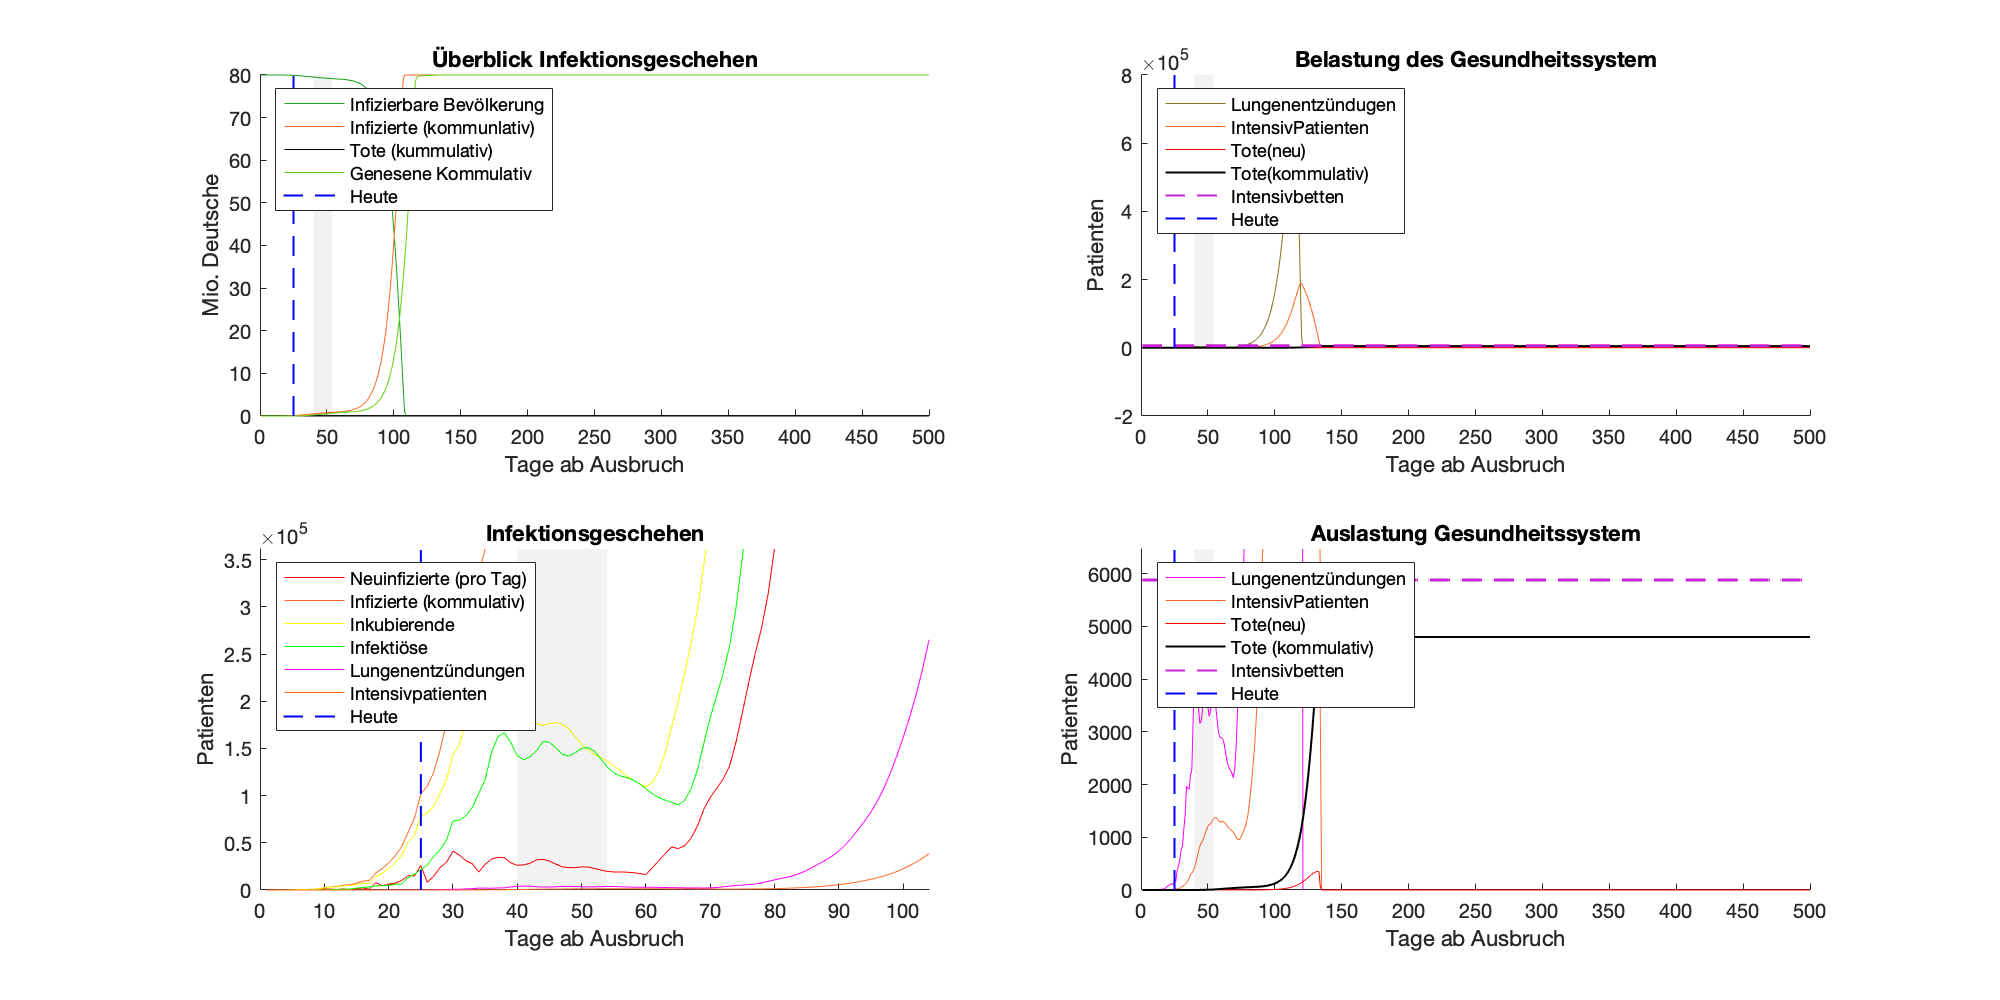





figure(2)

set(gcf,'Position',[10 10 1000 500])

p3 = subplot(2,2,1);
hold on
%Infizierbare Bevölkerung
plot(1:Vorhersagezeitraum,Population(1:Vorhersagezeitraum).*(1-AnteilImmuner(1:Vorhersagezeitraum)),'Color' ,[0.1098    0.6392    0.1098]);
%Infizierte Kommulativ
plot(bisherInfizierteAmTag,'Color', [1.0000    0.4118    0.1608]);
%Tote kommulativ
plot(bisherToteAmTag,'k');
%Genesene Kommulativ
plot(geneseneAmTag, 'Color', [ 0.3922    0.8314    0.0745]);

title('Überblick Infektionsgeschehen');
y = ylim; % current y-axis limits
plot([simStart simStart],[y(1) y(2)], 'LineStyle', "--", "LineWidth",1, 'Color', 'b');

if(AUSGANGSSPERREN)
    for i = 1:anzahl_der_Ausgangssperren
        x1 = ausgangssperren_Beginn_Ende_BasisrepZahl(1,i);
        x2 = ausgangssperren_Beginn_Ende_BasisrepZahl(2,i);
        boxx=[x1 x1 x2 x2];
        boxy=[0 y(2) y(2) 0];
        patch(boxx, boxy,[0 0 0],'FaceAlpha',max(ausgangssperren_Beginn_Ende_BasisrepZahl(3,i)*(-0.25)+0.25,0),'EdgeColor', 'none');
        
    end
end

yticks([0 10e6 20e6 30e6 40e6 50e6 60e6 70e6 80e6]);
yticklabels({'0','10','20','30','40','50','60','70','80'});
xlabel('Tage ab Ausbruch')
ylabel('Mio. Deutsche')
legend(p3,'Infizierbare Bevölkerung', 'Infizierte (kommunlativ)', 'Tote (kummulativ)','Genesene Kommulativ', 'Heute');
legend(p3, 'Location','NW');


%figure(3)
p2 = subplot(2,2,2);
hold on

plot(ZubehandelndeInfizierteAmTag,'Color',[ 0.5098    0.4588    0.1216])
plot(IntensivPatientenAmTag,'Color', [1.0000    0.4118    0.1608])
plot(ToteAmTag,'r')
plot(bisherToteAmTag,'k',"LineWidth",1)
plot(IntensivKapazitaet,'Color',[0.7843    0.1333    0.8314], 'LineStyle', "--", "LineWidth",1)

title('Belastung des Gesundheitssystem');


y = ylim; % current y-axis limits
plot([simStart simStart],[y(1) y(2)], 'LineStyle', "--", "LineWidth",1, 'Color', 'b');

if(AUSGANGSSPERREN)
    for i = 1:anzahl_der_Ausgangssperren
        x1 = ausgangssperren_Beginn_Ende_BasisrepZahl(1,i);
        x2 = ausgangssperren_Beginn_Ende_BasisrepZahl(2,i);
        boxx=[x1 x1 x2 x2];
        boxy=[0 y(2) y(2) 0];
        patch(boxx, boxy,[0 0 0],'FaceAlpha',max(ausgangssperren_Beginn_Ende_BasisrepZahl(3,i)*(-0.25)+0.25,0),'EdgeColor', 'none');
    end
else
    
end


xlabel('Tage ab Ausbruch')
ylabel('Patienten')
legend(p2,'Lungenentzündugen','IntensivPatienten','Tote(neu)','Tote(kommulativ)','Intensivbetten', 'Heute')
legend(p2,'Location','NW');


p5 = subplot(2,2,3);
hold on
%Neuinfizierte täglich
plot(neuInfizierteAmTag,'r');
%Infizierte Kommulativ
plot(bisherInfizierteAmTag,'Color', [1.0000    0.4118    0.1608]);
%Inkubierende
plot(InkubierendeInfizierteAmTag,'y');
%Infektiöse
plot(InfektioeseInfizierteAmTag, 'g');
%Lungenentzündungen
plot(ZubehandelndeInfizierteAmTag, 'm');
%Intensivpatienten
plot(IntensivPatientenAmTag,'Color', [1.0000    0.4118    0.1608]);

title('Infektionsgeschehen');
ylim([0 bisherInfizierteAmTag(simStart+10)])

y = ylim; % current y-axis limits
plot([simStart simStart],[y(1) y(2)], 'LineStyle', "--", "LineWidth",1, 'Color', 'b');


if(AUSGANGSSPERREN)
    xlim([0 ausgangssperren_Beginn_Ende_BasisrepZahl(2,end)+50]);
    for i = 1:anzahl_der_Ausgangssperren
        x1 = ausgangssperren_Beginn_Ende_BasisrepZahl(1,i);
        x2 = ausgangssperren_Beginn_Ende_BasisrepZahl(2,i);
        boxx=[x1 x1 x2 x2];
        boxy=[0 y(2) y(2) 0];
        patch(boxx, boxy,[0 0 0],'FaceAlpha',max(ausgangssperren_Beginn_Ende_BasisrepZahl(3,i)*(-0.25)+0.25,0),'EdgeColor', 'none');
    end
else
    xlim([0 simStart+50]);
end

xlabel('Tage ab Ausbruch')
ylabel('Patienten')
legend(p5, 'Neuinfizierte (pro Tag)', 'Infizierte (kommulativ)','Inkubierende','Infektiöse','Lungenentzündungen','Intensivpatienten', 'Heute');

legend(p5, 'Location','NW');


%figure(5)
p4 = subplot(2,2,4);
hold on
plot(ZubehandelndeInfizierteAmTag,'m')
plot(IntensivPatientenAmTag,'Color', [1.0000    0.4118    0.1608])
plot(ToteAmTag,'r')
plot(bisherToteAmTag,'k', "LineWidth",1)
plot(IntensivKapazitaet,'Color',[0.7843    0.1333    0.8314], 'LineStyle', "--", "LineWidth",1)

title('Auslastung Gesundheitssystem');
xlim([0 Vorhersagezeitraum]);
ylim([0 1.1*IntensivKapazitaet(end)]);



y = ylim; % current y-axis limits
plot([simStart simStart],[y(1) y(2)], 'LineStyle', "--", "LineWidth",1, 'Color', 'b');


if(AUSGANGSSPERREN)
    for i = 1:anzahl_der_Ausgangssperren
        x1 = ausgangssperren_Beginn_Ende_BasisrepZahl(1,i);
        x2 = ausgangssperren_Beginn_Ende_BasisrepZahl(2,i);
        boxx=[x1 x1 x2 x2];
        boxy=[0 y(2) y(2) 0];
        patch(boxx, boxy,[0 0 0],'FaceAlpha',max(ausgangssperren_Beginn_Ende_BasisrepZahl(3,i)*(-0.25)+0.25,0),'EdgeColor', 'none');
    end
end

xlabel('Tage ab Ausbruch')
ylabel('Patienten')
legend(p4, 'Lungenentzündungen','IntensivPatienten','Tote(neu)','Tote (kommulativ)','Intensivbetten', 'Heute')

legend(p4, 'Location','NW');

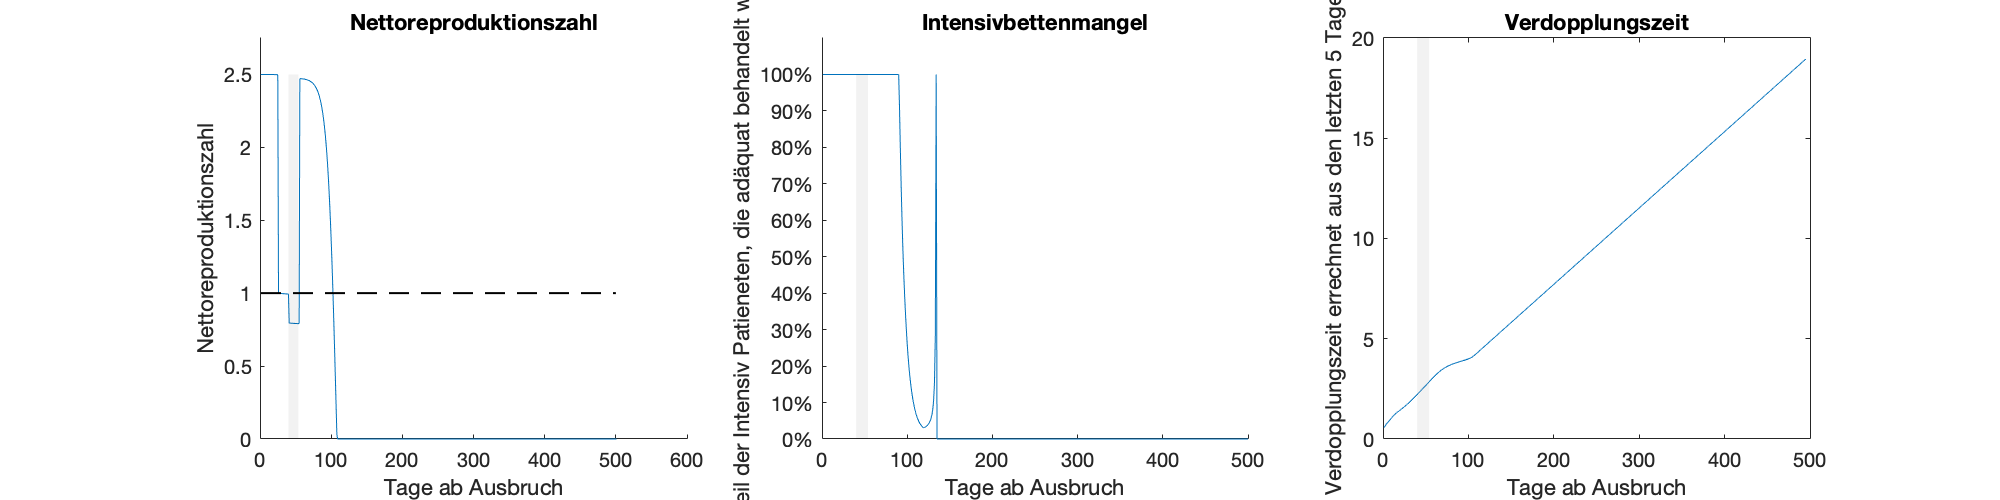



figure(3)
set(gcf,'Position',[10 10 1000 250])
subplot(1,3,1)
hold on
plot(NettoreproduktionszahlArray)
plot([1, Vorhersagezeitraum],[1 1], 'LineStyle', "--", "LineWidth",1, 'Color', 'k');
y = ylim;
if(AUSGANGSSPERREN)
    for i = 1:anzahl_der_Ausgangssperren
        x1 = ausgangssperren_Beginn_Ende_BasisrepZahl(1,i);
        x2 = ausgangssperren_Beginn_Ende_BasisrepZahl(2,i);
        boxx=[x1 x1 x2 x2];
        boxy=[0 y(2) y(2) 0];
        patch(boxx, boxy,[0 0 0],'FaceAlpha',max(ausgangssperren_Beginn_Ende_BasisrepZahl(3,i)*(-0.25)+0.25,0),'EdgeColor', 'none');
    end
end

title('Nettoreproduktionszahl');
xlabel('Tage ab Ausbruch');
ylabel('Nettoreproduktionszahl')
ylim([0 max(NettoreproduktionszahlArray)*1.1]);

subplot(1,3,2)
hold on
plot(anteilBeatmeterIntensivPatienten);
y = ylim;
if(AUSGANGSSPERREN)
    for i = 1:anzahl_der_Ausgangssperren
        x1 = ausgangssperren_Beginn_Ende_BasisrepZahl(1,i);
        x2 = ausgangssperren_Beginn_Ende_BasisrepZahl(2,i);
        boxx=[x1 x1 x2 x2];
        boxy=[0 y(2) y(2) 0];
        patch(boxx, boxy,[0 0 0],'FaceAlpha',max(ausgangssperren_Beginn_Ende_BasisrepZahl(3,i)*(-0.25)+0.25,0),'EdgeColor', 'none');
    end
end

title('Intensivbettenmangel')
xlabel('Tage ab Ausbruch');
ylabel('Anteil der Intensiv Patieneten, die adäquat behandelt werden')
ylim([0 1.1])
yticks([0 0.1 0.2 0.3 0.4 0.5 0.6 0.7 0.8 0.9 1]);
yticklabels({'0%','10%','20%','30%','40%','50%','60%','70%','80%', '90%', '100%'});

subplot(1,3,3)

rueckSchau_Zeitraum = 5;

for index = round(rueckSchau_Zeitraum+1:1:Vorhersagezeitraum)
    indizes = index-rueckSchau_Zeitraum: index;
    x= transpose(indizes);
    y =transpose(log(bisherInfizierteAmTag(indizes)));
    m(index) = x\y;
end

verdopplungzeit= log(2)./m(m~=0);
plot(verdopplungzeit);
y = ylim;
if(AUSGANGSSPERREN)
    for i = 1:anzahl_der_Ausgangssperren
        x1 = ausgangssperren_Beginn_Ende_BasisrepZahl(1,i);
        x2 = ausgangssperren_Beginn_Ende_BasisrepZahl(2,i);
        boxx=[x1 x1 x2 x2];
        boxy=[0 y(2) y(2) 0];
        patch(boxx, boxy,[0 0 0],'FaceAlpha',max(ausgangssperren_Beginn_Ende_BasisrepZahl(3,i)*(-0.25)+0.25,0),'EdgeColor', 'none');
    end
end

title('Verdopplungszeit')
xlabel('Tage ab Ausbruch');
ylabel(sprintf('Verdopplungszeit errechnet aus den letzten %.0f Tagen', rueckSchau_Zeitraum));